Here is the Matlab live script that can be run to see the chi square statistics when testing with the (60:50) data set

[status,sheets] = xlsfinfo('Nguyen D-Proj2020')%shows that 3 sheets exist

status = 'Microsoft Excel Spreadsheet'

sheets = 1×3 cell array
    {'Sheet1'}    {'Sheet2'}    {'Sheet3'}


% the command to read the data
[A,names,raw] =xlsread('Nguyen D-Proj2020',1);% reads the first sheet only
LN=length(names); % number of columns with names
A ;% data only
names; % headers
raw; % headers and data
data = A(:,1);% get the first colum data
% x and y are of different lengths. Because of this, y contains NaN
 % suppress the NaN

target_abs = data((1:70),:);
target_pre = sort(data((71:130),:),'descend');

N0=length(target_abs);
N1=length(target_pre);

% pick best fir cho absent va present dua vao p value cao nhat 

[parG_pre] = fitdist(target_pre, 'gamma');
[h,  p, stats] = chi2gof(target_pre, 'CDF', parG_pre)

h = 0

p = 0.5153

stats = struct with fields:
    chi2stat: 3.2597
          df: 4
       edges: [1.2206 2.0202 2.8198 3.6194 4.4190 5.2186 6.0181 9.2165]
           O: [10 7 9 9 9 8 8]
           E: [7.9619 9.4401 10.3459 9.3387 7.4479 5.4515 10.0140]



[parW_pre] = fitdist(target_pre, 'Weibull');
[h,  p, stats] = chi2gof(target_pre, 'CDF', parW_pre)

h = 0

p = 0.8204

stats = struct with fields:
    chi2stat: 1.5349
          df: 4
       edges: [1.2206 2.0202 2.8198 3.6194 4.4190 5.2186 6.0181 9.2165]
           O: [10 7 9 9 9 8 8]
           E: [8.7502 8.0270 9.2102 9.1273 8.0064 6.2926 10.5863]



[parN_pre] = fitdist(target_pre, 'Nakagami');
[h,  p, stats] = chi2gof(target_pre, 'CDF', parN_pre)

h = 0

p = 0.7884

stats = struct with fields:
    chi2stat: 1.7125
          df: 4
       edges: [1.2206 2.0202 2.8198 3.6194 4.4190 5.2186 6.0181 9.2165]
           O: [10 7 9 9 9 8 8]
           E: [8.2615 8.1992 9.4895 9.3428 8.0831 6.2536 10.3703]



[parR_pre] = fitdist(target_pre, 'rician');
[h,  p, stats] = chi2gof(target_pre, 'CDF', parR_pre)

h = 0

p = 0.8093

stats = struct with fields:
    chi2stat: 1.5973
          df: 4
       edges: [1.2206 2.0202 2.8198 3.6194 4.4190 5.2186 6.0181 9.2165]
           O: [10 7 9 9 9 8 8]
           E: [9.6695 7.9511 8.9002 8.7741 7.7471 6.1705 10.7874]



[parRa_pre] = fitdist(target_pre, 'rayleigh');
[h,  p, stats] = chi2gof(target_pre, 'CDF', parRa_pre)

h = 0

p = 0.8062

stats = struct with fields:
    chi2stat: 2.3001
          df: 5
       edges: [1.2206 2.0202 2.8198 3.6194 4.4190 5.2186 6.0181 9.2165]
           O: [10 7 9 9 9 8 8]
           E: [10.5343 8.2754 8.9042 8.4648 7.2771 5.7285 10.8157]



disp('a')

a



[parG_abs] = fitdist(target_abs, 'gamma');
[h,  p, stats] = chi2gof(target_abs, 'CDF', parG_abs)

h = 0

p = 0.5602

stats = struct with fields:
    chi2stat: 2.9860
          df: 4
       edges: [0.1648 0.5838 1.0029 1.4219 1.8409 2.2600 2.6790 4.3551]
           O: [8 10 14 11 6 9 12]
           E: [6.8550 12.4159 13.3905 11.5053 8.7491 6.1647 10.9194]



[parW_abs] = fitdist(target_abs, 'Weibull');
[h,  p, stats] = chi2gof(target_abs, 'CDF', parW_abs)

h = 0

p = 0.6574

stats = struct with fields:
    chi2stat: 2.4291
          df: 4
       edges: [0.1648 0.5838 1.0029 1.4219 1.8409 2.2600 2.6790 4.3551]
           O: [8 10 14 11 6 9 12]
           E: [7.2136 10.8536 12.4580 11.7918 9.7224 7.1571 10.8035]



[parN_abs] = fitdist(target_abs, 'Nakagami');
[h,  p, stats] = chi2gof(target_abs, 'CDF', parN_abs)

h = 0

p = 0.6663

stats = struct with fields:
    chi2stat: 2.3799
          df: 4
       edges: [0.1648 0.5838 1.0029 1.4219 1.8409 2.2600 2.6790 4.3551]
           O: [8 10 14 11 6 9 12]
           E: [7.3774 10.6849 12.2711 11.7331 9.7896 7.2738 10.8701]



[parR_abs] = fitdist(target_abs, 'Rician');
[h,  p, stats] = chi2gof(target_abs, 'CDF', parR_abs)

h = 0

p = 0.5091

stats = struct with fields:
    chi2stat: 3.2988
          df: 4
       edges: [0.1648 0.5838 1.0029 1.4219 1.8409 2.2600 2.6790 4.3551]
           O: [8 10 14 11 6 9 12]
           E: [6.0183 10.2909 12.6213 12.4334 10.4357 7.6560 10.5444]



[parRa_abs] = fitdist(target_abs, 'rayleigh');
[h,  p, stats] = chi2gof(target_abs, 'CDF', parRa_abs)

h = 0

p = 0.6539

stats = struct with fields:
    chi2stat: 3.2994
          df: 5
       edges: [0.1648 0.5838 1.0029 1.4219 1.8409 2.2600 2.6790 4.3551]
           O: [8 10 14 11 6 9 12]
           E: [6.0204 10.2940 12.6240 12.4347 10.4351 7.6543 10.5375]


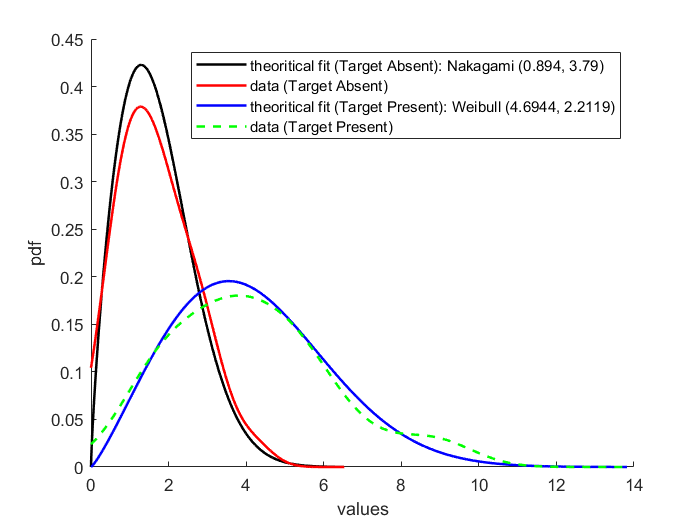

figure;hold on
xx0=0:0.01:1.5*max(target_abs);
xx1=0:0.01:1.5*max(target_pre);
fx0=ksdensity(target_abs,xx0,'function', 'pdf');
fx1=ksdensity(target_pre,xx1,'function','pdf');

% besfit for assent
Nakadata = fitdist(target_abs, 'Nakagami');
Naka = pdf(Nakadata,xx0);
plot(xx0, Naka, '-k', 'linewidth', 1.5)
plot(xx0, fx0, '-r', 'linewidth',1.5);

% bestfit for present
Weibulldata = fitdist(target_pre, 'Weibull');
Weibull = pdf(Weibulldata,xx1);
plot(xx1, Weibull, '-b', 'linewidth', 1.5)

fit1 = plot(xx1, fx1, '-g', 'linewidth',1.5);
fit1.LineStyle = '--';

ylabel('pdf'); xlabel('values');
legend('theoritical fit (Target Absent): Nakagami (0.894, 3.79)', ...
'data (Target Absent)',...
'theoritical fit (Target Present): Weibull (4.6944, 2.2119)', ...
'data (Target Present)');

thr=0:0.2:150;

% besfit cho absent va present
Abs1=fitdist(target_abs,'Nakagami');
Prs1=fitdist(target_pre,'Weibull');

% chinh lai distribution va parameter theo data cua minh

%pfg= 1 - cdf('Nakakami',thr,Abs1.a,Abs1.b);
%pdg = 1 - cdf('Weibull',thr,Prs1.a,Prs1.b);
pfg= 1 - cdf('Nakagami',thr,0.894,3.79);
pdg = 1 - cdf('Weibull',thr,4.6944,2.2119);



figure,plot(pfg,pdg,'--r','linewidth',1.5)
hold on
resp=[zeros(N0,1);ones(N1,1)]; % labels
% Hanley & McNeil
[pf,pd,T,AUC,OPTOCPT]=perfcurve(resp,data,1)

pf =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pd =          0
    0.0167
    0.0333
    0.0500
    0.0667
    0.0833
    0.1000
    0.1167
    0.1333
    0.1500


T =     9.2165
    9.2165
    8.9182
    8.8186
    8.5828
    7.5879
    6.8511
    6.8406
    6.0584
    5.8203


AUC = 0.8710

OPTOCPT =     0.0571    0.6667


plot(pf,pd,'k','linewidth',1.5)
hold on
line =0:0.01:1

line =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


plot(line,line,'b')

% simulation
Atrap = abs(trapz(pfg,pdg))

Atrap = 0.8717

Az = polyarea(pfg,pdg) + 0.5

Az = 0.8717


nb = 5000

nb = 5000

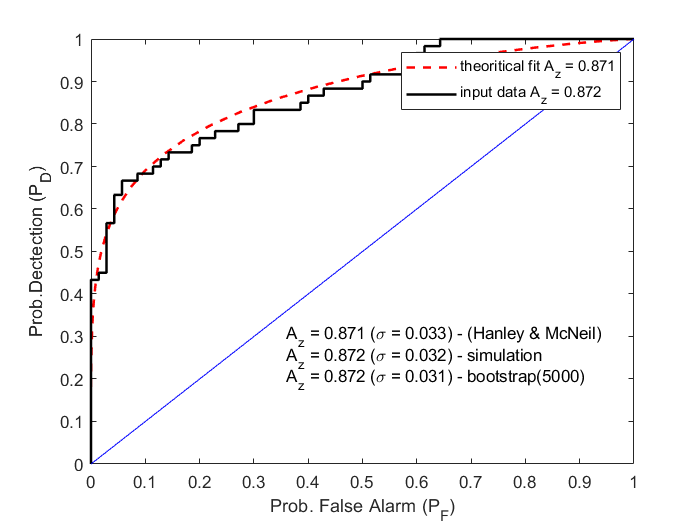


text(0.36,0.3,'A_z = 0.871 (\sigma = 0.033) - (Hanley & McNeil)')
text(0.36,0.25,'A_z = 0.872 (\sigma = 0.032) - simulation')
text(0.36,0.2,'A_z = 0.872 (\sigma = 0.031) - bootstrap(5000)')

legend('theoritical fit A_z = 0.871','input data A_z = 0.872')
xlabel('Prob. False Alarm (P_F)'),ylabel('Prob.Dectection (P_D)')

hold off

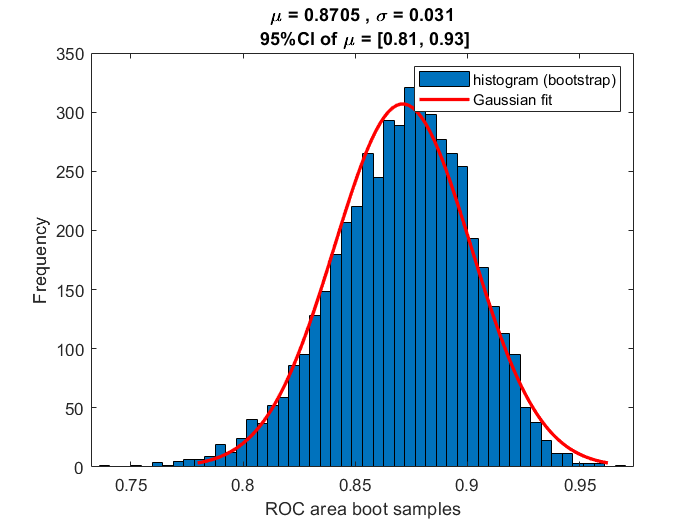

nB_AUC=5000;%boostrap
btarea=bootstrp(nB_AUC,@calculateROCarea,resp,data);
histfit(btarea,50) % get a histogram of the mean and a Gaussian fit
title({"\mu = 0.8705 , \sigma = 0.031" , " 95%CI of \mu = [0.81, 0.93]"})      
xlabel('ROC area boot samples'), ylabel('Frequency')
legend('histogram (bootstrap)', 'Gaussian fit')

mean_auc = mean(btarea)

mean_auc = 0.8712

stdbootstrap = std(btarea)

stdbootstrap = 0.0305



A1 = Az / (2 - Az)

A1 = 0.7726

A2 = 2 * (Az)^2 / (1 + Az)

A2 = 0.8119

stdAUC = sqrt((Az * (1-Az) + (N1 - 1) * (A1 - (Az)^2) + (N0 - 1) * (A2 - (Az)^2)) / ( N1 * N0) )

stdAUC = 0.0326


prctile(btarea,2.5) % 2.5%

ans = 0.8059

prctile(btarea,97.5) % 97.5%

ans = 0.9248

function area=calculateROCarea(resp,data)
[pf,pd,T,AUC]=perfcurve(resp,data,1);
area=AUC;
end